## Spline Interpolation

In this livescript, you will learn how

- To use low order spline interpolation to approximate functions.

- To generalise to higher order splines.

We'll consider approximating the Logistic curve


$$f(x)=\frac{1}{1+e^{-10x}}$$


with 7 points between $-5\leq x \leq 5$.

The function values at the nodes is given by

nodes = linspace(-5,5,7);
f = 1./(1+exp(-10*nodes));

To get an idea of what the function looks like

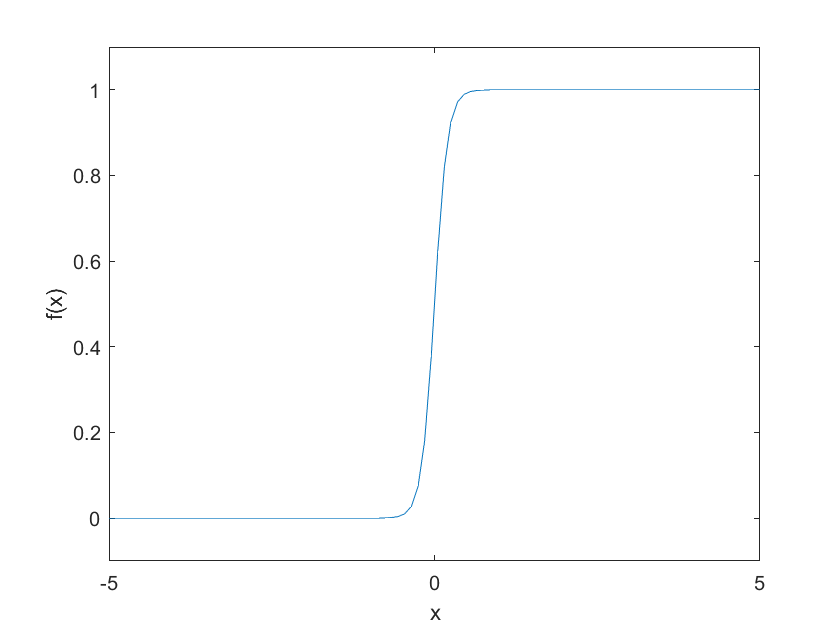

plot(linspace(-5,5,100),1./(1+exp(-10*linspace(-5,5,100))))
ylim([-0.1,1.1])
xlabel('x')
ylabel('f(x)')

Using Lagrange interpolation, we have

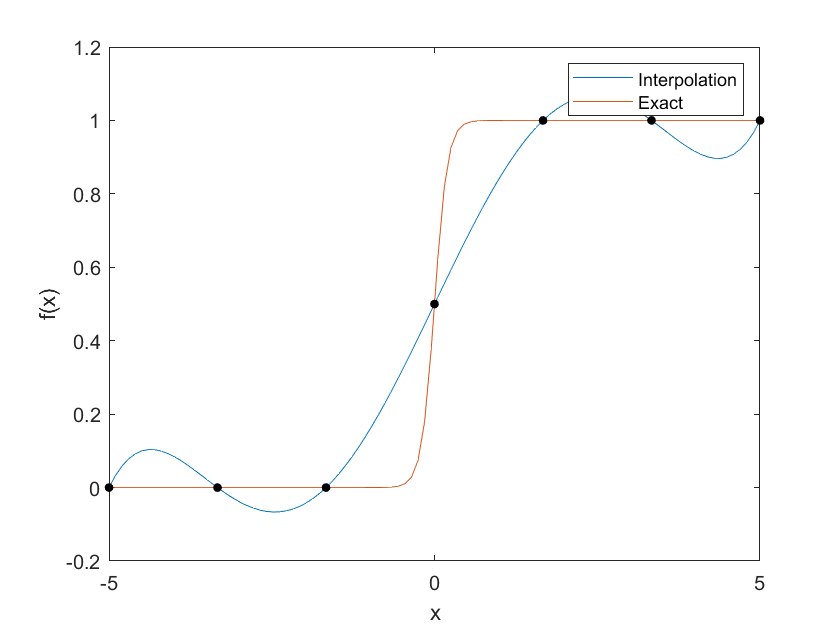

x1 = linspace(-5,5,100);
y1 = 0;

for l = 1:length(nodes)
    y1 = y1+f(l)*lagrange_L(l,nodes,x1);
end

plot(x1,y1)
hold on
plot(x1,1./(1+exp(-10*x1)))
plot(nodes,f,'.k','MarkerSize',15)
xlabel('x')
ylabel('f(x)')
legend('Interpolation','Exact')
hold off

What we see is that rapid change in the slope of $f$ causes the Lagrange polynomial to oscillate wildly. 

The problem arises because polynomials have derivatives that are continuous of all orders. 

This means that by adding interpolating points, we're increasing the order of the polynomial. And hence, the number of nonzero derivatives grows as well.

If these interpolation points are chosen poorly, then the magnitude of the derivatives will grow quite quickly. We'll see this later.

The idea with using splines is that we can dampen out the oscillations by using lower order polynomials between each of the nodes.

To get an idea of what our spline interpolation will look like, MATLAB has the inbuilt function $\texttt{spline(x,y,xp)}$ that determines the cubic spline interpolant.

$\texttt{spline(x,y,xp)}$ takes the $\texttt{x}$ and $\texttt{y}$ data as well as the query points $\texttt{xp}$.

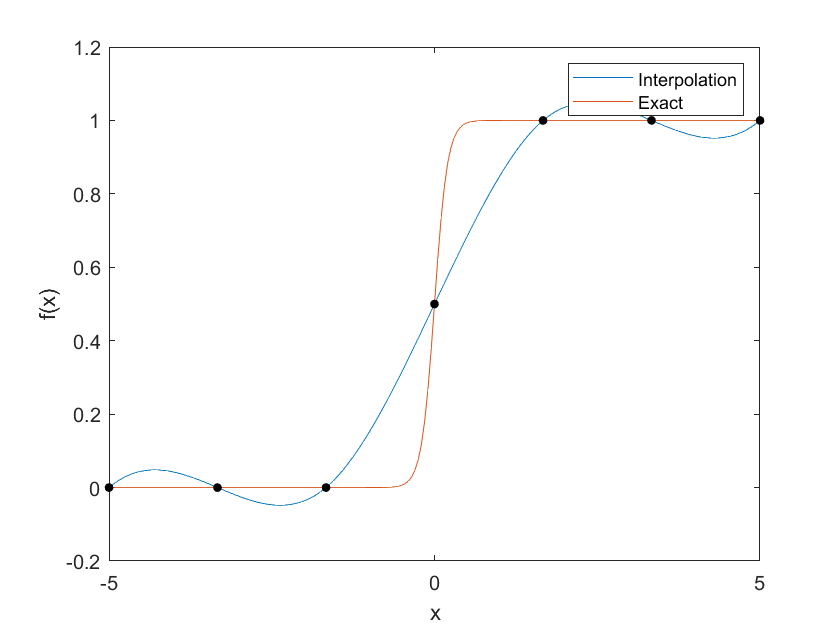

xp = -5:0.05:5;

s = spline(nodes,f,xp);
plot(xp,s)
hold on 
plot(xp,1./(1+exp(-10*xp)))
plot(nodes,f,'.k','MarkerSize',15)
hold off
xlabel('x')
ylabel('f(x)')
legend('Interpolation','Exact')

And we can plot the error as

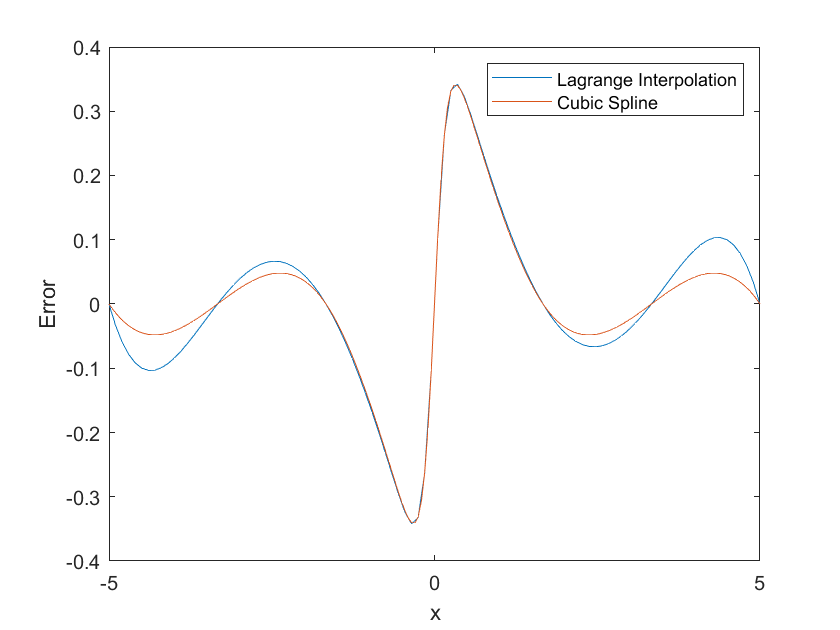

plot(x1,1./(1+exp(-10*x1))-y1')
hold on
plot(xp,1./(1+exp(-10*xp))-s)
xlabel('x')
ylabel('Error')
legend('Lagrange Interpolation','Cubic Spline')
hold off

We can see that the use of a spline interploant lessens the magnitude of the oscillations near the ends.

### Linear Splines

The easiest way of implementing a spline is to 'connect the dots'. Which we can do by assuming the linear relationship


$$S_{i}(x)=a_{i}+b_{i}(x-x_{i})$$


for $x_{i}<x<x_{i+1}$.

As we require the interpolant to be continuous, then we must have the boundary conditions 

- 
$$S_{i}(x_{i})=f(x_{i})$$


- 
$$S_{i}(x_{i+1})=S_{i+1}(x_{i+1})$$


(a)        Show that the coefficients are given by


$$a_{i}=f(x_{i})\\
b_{i}=\frac{f(x_{i+1})-f(x_{i})}{x_{i+1}-x_{i}}$$


Constructing these coefficients is in fact quite easy, as $a_{i}$ and $b_{i}$ only depend on the known values $f(x_{i})$. However, this is not always the case, as we'll see later.

So, our coefficients are therefore given by

xdata = linspace(-5,5,7);
fdata = 1./(1+exp(-10*xdata));

a = fdata(1:end-1);
b = (fdata(2:end)-fdata(1:end-1))./(xdata(2:end)-xdata(1:end-1));

Now that we've determined our interpolant, we would like to use it to find the value for some arbitrary $x$. However, we need some way of determining which segment $x$ is in.

A simple way to do this is to loop through each segment and check whether $x$ lies within said segment.

x = 4

x = 4


for j=1:length(xdata)-1
    if xdata(j)>x 
        f=a(j-1)+b(j-1)*(x-xdata(j-1));  
        break 
    end 
end

f

f =     0.0000    0.0000    0.0000    0.5000    1.0000    1.0000    1.0000


Putting this together gives 

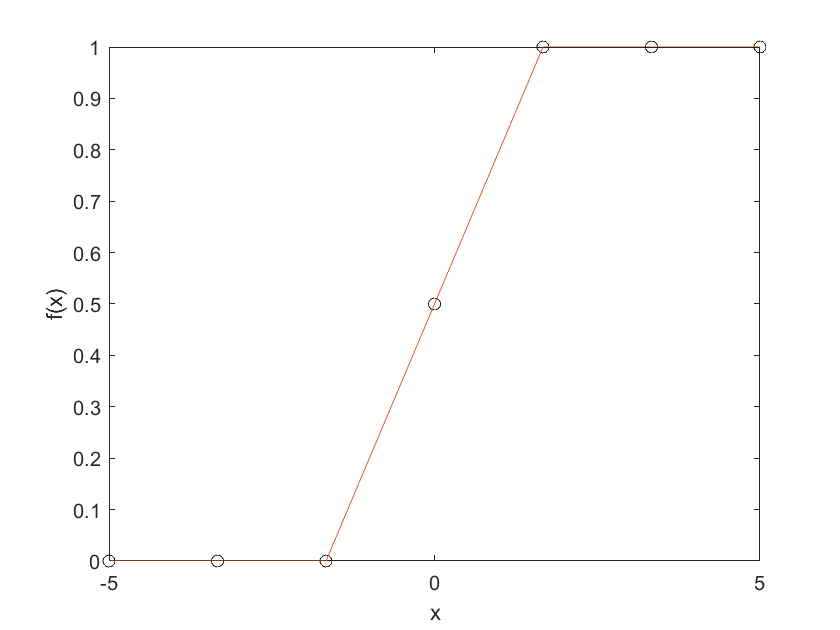

xdata = linspace(-5,5,7);
fdata = 1./(1+exp(-10*xdata));

a = fdata(1:end-1);
b = (fdata(2:end)-fdata(1:end-1))./(xdata(2:end)-xdata(1:end-1));

x = linspace(xdata(1),xdata(end),100);
f = zeros(1,length(x));

for i = 1:length(x)
    for j=2:length(xdata)
        if xdata(j)>=x(i) 
            f(i)=a(j-1)+b(j-1)*(x(i)-xdata(j-1));  
            break 
        end 
    end 
end

plot(xdata, fdata,'ko',x,f); 
xlabel('x');
ylabel('f(x)');

(b)        Run the code and check whether the code provides the expected output.

(c)        Rewrite the code a a function that takes the same inputs as $\texttt{spline}$.

### Quadratic Splines

While linear splines are simple to visualise and construct, and able to very accurately represent our original function $f$ by increasing the number of sampling points; the main issue with them is that the interpolant is usually not differentiable at the which at the interpolation nodes. 

This can be quite a big issue for some analyses. For example, the shear stress in a fluid is determined by the gradient of the velocity.

Therefore, we should extend our splines so that the derivatives are continuous at the interpolaltion points. This now gives us three conditions, which can be handled uniquely using a quadratic polynomial.


$$S_{i}(x)=a_{i}+b_{i}(x-x_{i})+c_{i}(x-x_{i})^{2}$$


for $x_{i}<x<x_{i+1}$.

**Boundary conditions**

        1. The interpolant should give the same outputs as the data at the nodes

$S_{i}(x_{i})=f(x_{i})$ at $x=x_{i}$.

        2. Continuity of the splines at $x=x_{i+1}$.


$$S_{i}(x_{i})=S_{i+1}(x_{i+1})$$


        3. Continuity of the derivative at $x=x_{i+1}$.


$$S^{'}_{i}(x_{i})=S^{'}_{i+1}(x_{i+1})$$


(a)        Show that the the boundary conditions give rise to the coefficients


$$a_{i}=f(x_{i})\\
b_{i}=\frac{a_{i+1}-a_{i}}{h_{i}}-c_{i}h_{i}\\
c_{i}=\frac{1}{h_{i}}\Big(\frac{a_{i+1}}{h_{i}}-a_{i}\Big[\frac{1}{h_{i-1}}+\frac{1}{h_{i}}\Big]+\frac{a_{i-1}}{h_{i-1}}-c_{i-1}h_{i-1}\Big)$$


where $h_{i}=x_{i+1}-x_{i}$.

What we see is that the coefficients $b_{i}$ are dependent on $c_{j}$ and $a_{j}$, whereas $c_{i}$ is only dependent on $a_{j}$, and $a_{i}$ only on the sampled values $f(x_{j})$.

So, in order to construct our splines, we 

**Step 1.** Determine the vector $\{a\}$ by setting it as equal to the data $\{f_{\text{data}}\}$.

A piece of code that does this 

xdata = linspace(-5,5,7);
fdata = 1./(1+exp(-10*xdata));

a = fdata;

**Step 2.** Since $c_{i}$ is defined recusively, we need to assume an initial condition $c_{0}$. For simplicity, if we let $c_{0}=0$, then the first segment is linear.

c = zeros(1,length(xdata)-1);
c(1) = 0;

**Step 3.** Use our vector $\{a\}$ to determine the vector $\{c\}$.

Since there are 6 sampling points, we know that there must be $N=6-1=5$ segments. So, we can use a for loop to determine the coefficients.

h = xdata(2:end)-xdata(1:end-1);

for i = 2:length(xdata)-1
    c(i) = (1/h(i))*(a(i+1)/h(i)-a(i)*((1/h(i-1))+(1/h(i)))+a(i-1)/h(i-1)-c(i-1)*h(i-1)); 
end 

**Step 4. **Use our vector $\{c\}$ to determine the vector $\{b\}$.

b = zeros(1,length(xdata));

for i=1:length(xdata)-1
    b(i)=(a(i+1)-a(i))/h(i)-c(i)*h(i); 
end 

**Step 5.** Using our search program from earlier, we can evaluate our interpolant at an arbitrary $x$.

x = 4;

for j=1:length(xdata)-1
    if xdata(j)>x 
        f=a(j-1)+b(j-1)*(x-xdata(j-1))+c(j-1)*(x-xdata(j-1))^2;  
        break 
    end 
end 

Putting this all together gives the piece of code

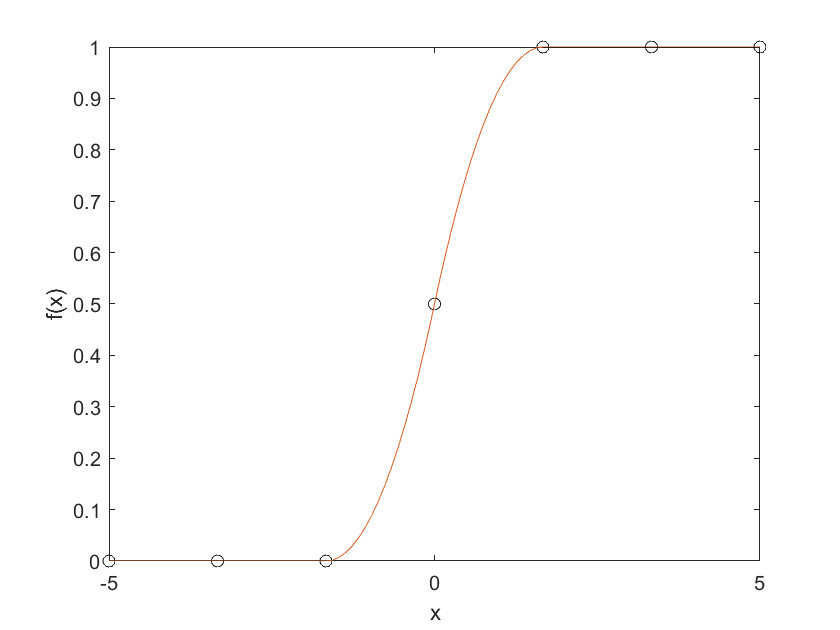

xdata = linspace(-5,5,7);
fdata = 1./(1+exp(-10*xdata));

a = fdata;

c = zeros(1,length(xdata));
c(1) = 0;

h = xdata(2:end)-xdata(1:end-1);

for i = 2:length(xdata)-1
    c(i) = (1/h(i))*(a(i+1)/h(i)-a(i)*((1/h(i-1))+(1/h(i)))+a(i-1)/h(i-1)-c(i-1)*h(i-1)); 
end 

b = zeros(1,length(xdata));

for i=1:length(xdata)-1
    b(i)=(a(i+1)-a(i))/h(i)-c(i)*h(i); 
end 

x = linspace(xdata(1),xdata(end),100);
f = zeros(1,length(x));

for i = 1:length(x)
    for j=2:length(xdata)
        if xdata(j)>=x(i) 
            f(i)=a(j-1)+b(j-1)*(x(i)-xdata(j-1))+c(j-1)*(x(i)-xdata(j-1))^2;  
            break 
        end 
    end 
end

plot(xdata, fdata,'ko',x,f);
xlabel('x');
ylabel('f(x)');

(b)        Run the code and check whether the code provides the expected output.

(c)        Rewrite the code a a function that takes the same inputs as $\texttt{spline}$.

(d)        Compare the results with a cubic spline using $\texttt{spline}$.